# Using Detection Models on Images and Video

In this script you'll load and use pre-trained models for object detection. These detectors are trained to detect 80 classes of objects and can be used without training.

**Note**: Running this script will save a small video file named "pedTrackingWithDetections.mp4" to your Current Folder. Watch this video to see how well the detector finds people and cars.

## YOLO v4 and YOLOX Object Detectors

The YOLO object detection frameworks are widely known and used due to their speed and accuracy. In this course you will use two YOLO frameworks.

YOLO v4 is widely used and requires anchor boxes. There are two backbones to choose from with YOLO v4.

- "`csp-darknet-53-coco`" uses the full Darknet-53 backbone with three neck attachments

- "`tiny-yolov4-coco`" uses a tiny version of the Darknet-53 backbone and has two neck attachments

YOLOX is the latest version of the YOLO framework and does not require anchor boxes. There are two backbones to choose from.

- "`small-coco`" uses "small" version of the Darknet-53 backbone and has three neck attachments

- "`tiny-coco`" uses a "tiny" version of the Darknet-53 backbone and has three neck attachments

Don't worry about anchor boxes right now. You'll learn how create and use them later. 

### Create object detectors

Run this section to create four different object detection models. Note that it will take a little time to load the detectors.

v4dark = yolov4ObjectDetector("csp-darknet53-coco");
v4tiny = yolov4ObjectDetector("tiny-yolov4-coco");
yoloXsmall = yoloxObjectDetector("small-coco");
yoloXtiny = yoloxObjectDetector("tiny-coco");

### Compare model sizes

The size of the backbone greatly impacts the number of learnable parameters and model size. YOLO v4 with the "`csp-darknet53-coco`" backbone has *nine* times the parameters as the "tiny" backbone and seven times the "small." The extra complexity results in a larger model and slower prediction speeds but can give more accurate results in some applications. 

whos v4dark v4tiny yoloXsmall yoloXtiny

  Name            Size                Bytes  Class                   Attributes

  v4dark          1x1             259226864  yolov4ObjectDetector              
  v4tiny          1x1              24522430  yolov4ObjectDetector              
  yoloXsmall      1x1              37391641  yoloxObjectDetector               
  yoloXtiny       1x1              21590959  yoloxObjectDetector               



### What objects can these pre-trained models detect?

The [COCO object detection dataset](https://cocodataset.org/#detection-2020) has 80 objects. Run this section to see what objects these models are trained to detect.

classes = v4tiny.ClassNames

classes = 80×1 cell array
    {'person'       }
    {'bicycle'      }
    {'car'          }
    {'motorbike'    }
    {'aeroplane'    }
    {'bus'          }
    {'train'        }
    {'truck'        }
    {'boat'         }
    {'traffic light'}
    {'fire hydrant' }
    {'stop sign'    }
    {'parking meter'}
    {'bench'        }
    {'bird'         }
    {'cat'          }
    {'dog'          }
    {'horse'        }
    {'sheep'        }
    {'cow'          }
    {'elephant'     }
    {'bear'         }
    {'zebra'        }
    {'giraffe'      }
    {'backpack'     }
    {'umbrella'     }
    {'handbag'      }
    {'tie'          }
    {'suitcase'     }
    {'frisbee'      }


## Apply the Detectors to Images

Load and view an image. There are six people in the image, one is partially obscured.

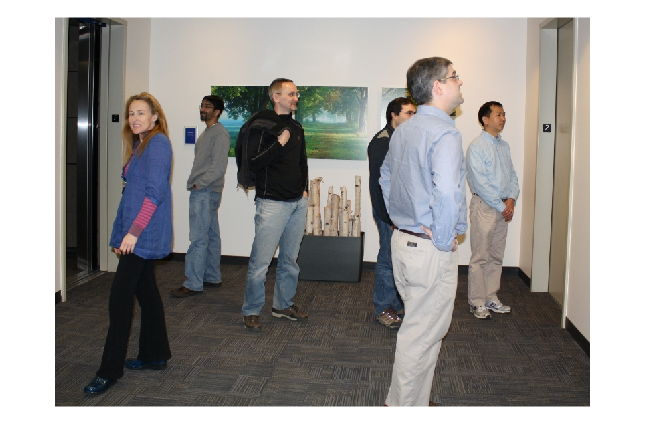

img = imread("visionteam1.jpg");
imshow(img)

The code below applies the detector to the image with the `detect` function. The outputs are the bounding boxes of detected objects, the detector's confidence score in those detection, and the label for each object.

Use the `insertObjectAnnotation `function to visualize the results. The `tic` and `toc` functions are used to compare prediction speeds.

**YOLO v4 with Darknet backbone**

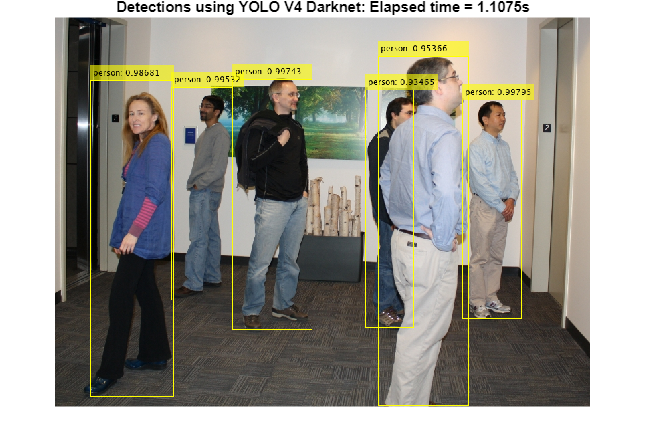

% detect objects and find the prediction time
tstart = tic;
[bboxes,scores,labels] = detect(v4dark,img);
tElapsed = toc(tstart);

% add the the predictions to the image
txt = string(labels) + ": " + scores;
imgV4dark = insertObjectAnnotation(img,"rectangle",bboxes,txt);

% visualize the results
imshow(imgV4dark)
title("Detections using YOLO V4 Darknet: Elapsed time = " + tElapsed + "s")

**YOLO v4 with tiny backbone**

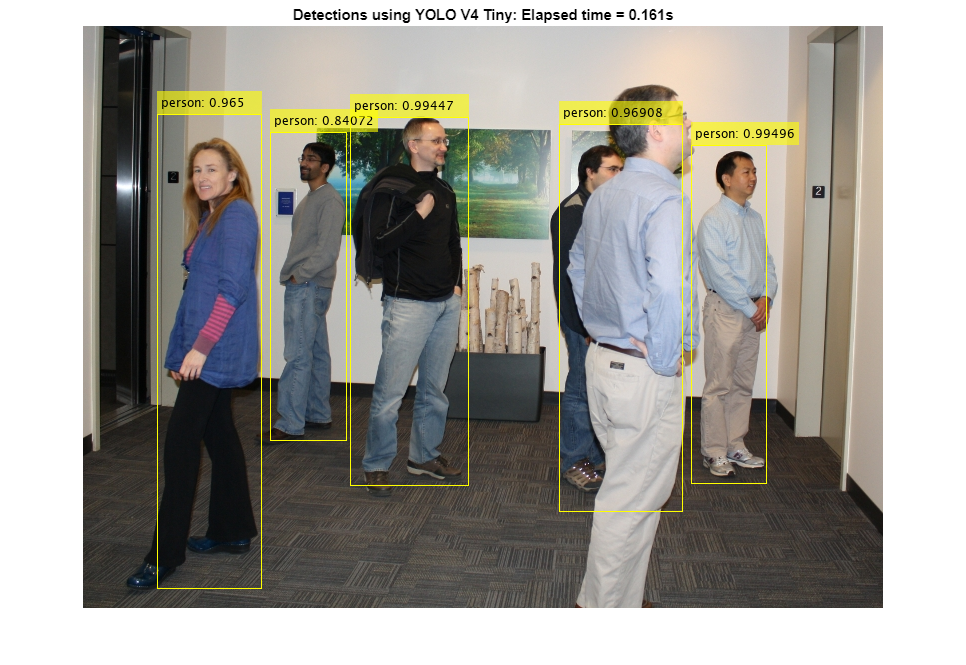

% detect objects and find the prediction time
tstart = tic;
[bboxes,scores,labels] = detect(v4tiny,img);
tElapsed = toc(tstart);

% add the the predictions to the image
txt = string(labels) + ": " + scores;
imgV4tiny = insertObjectAnnotation(img,"rectangle",bboxes,txt);

% visualize the results
imshow(imgV4tiny)
title("Detections using YOLO V4 Tiny: Elapsed time = " + tElapsed + "s")

### You try with YOLOX

Notice that YOLO v4 with the Darknet backbone took significantly more time to make predictions, but found all six people in the image. Using the tiny backbone was much faster but the two overlapping people were detected as one person. 

Repeat the detections with the two YOLOX detectors. What is the result?

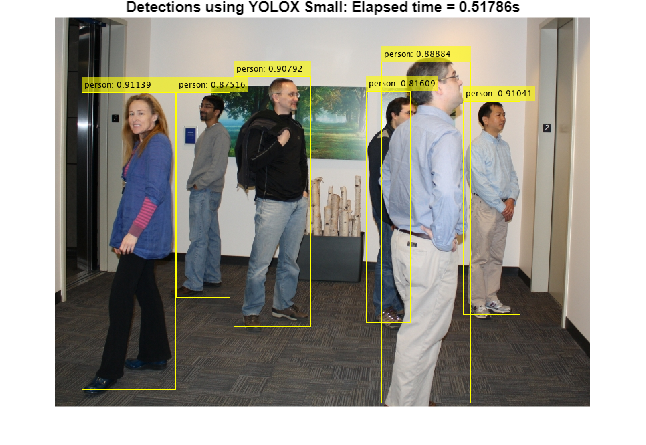

% detect objects and find the prediction time
tstart = tic;
[bboxes,scores,labels] = detect(yoloXsmall,img);
tElapsed = toc(tstart);

% add the the predictions to the image
txt = string(labels) + ": " + scores;
imgXsmall = insertObjectAnnotation(img,"rectangle",bboxes,txt);

% visualize the results
imshow(imgXsmall)
title("Detections using YOLOX Small: Elapsed time = " + tElapsed + "s")

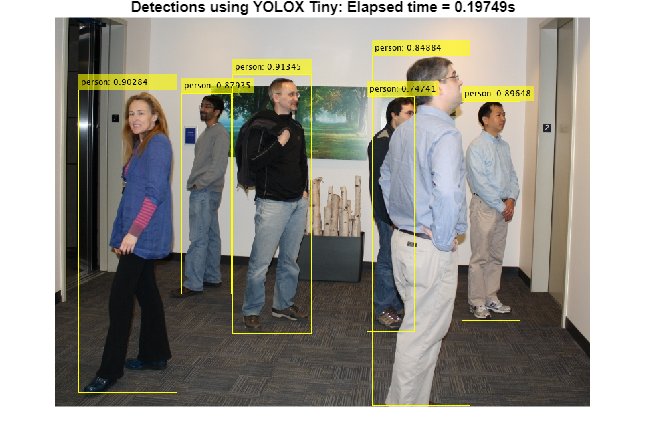

% detect objects and find the prediction time
tstart = tic;
[bboxes,scores,labels] = detect(yoloXtiny,img);
tElapsed = toc(tstart);

% add the the predictions to the image
txt = string(labels) + ": " + scores;
imgXtiny = insertObjectAnnotation(img,"rectangle",bboxes,txt);

% visualize the results
imshow(imgXtiny)
title("Detections using YOLOX Tiny: Elapsed time = " + tElapsed + "s")

## Adjusting the Detection Confidence Threshold

The `scores` output represents the detector's confidence in the predictions. Only detections with confidence scores above a threshold are returned. The default values are:

- 0.5 for YOLO v4 detectors

- 0.25 for YOLOX detectors  

You can increase or decrease this value to make the detector more strict or less strict respectively.

Since the YOLO v4 tiny model did not detect all six people, try lowering the confidence threshold. Are all six people detected? Are any other objects returned?

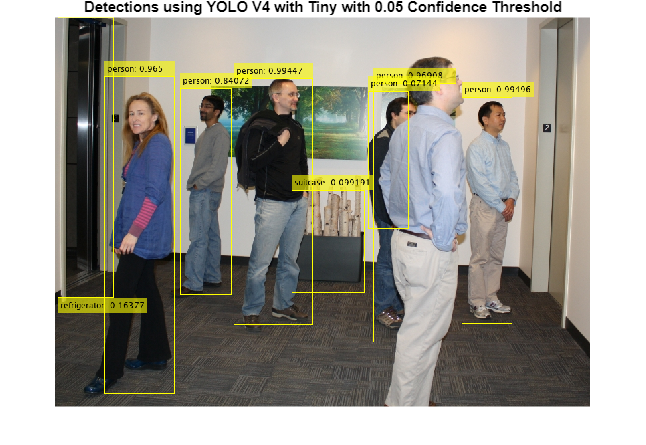

[bboxes,scores,labels] = detect(v4tiny,img,"Threshold",0.05);
txt = string(labels) + ": " + scores;
imgVtiny = insertObjectAnnotation(img,"rectangle",bboxes,txt);
imshow(imgVtiny)
title("Detections using YOLO V4 with Tiny with 0.05 Confidence Threshold")

[bboxes,scores,labels] = detect(v4tiny,img,"Threshold",0.05);
txt = string(labels) + ": " + scores;
imgVtiny = insertObjectAnnotation(img,"rectangle",bboxes,txt);
imshow(imgVtiny)
title("Detections using YOLO V4 with Tiny with 0.05 Confidence Threshold")

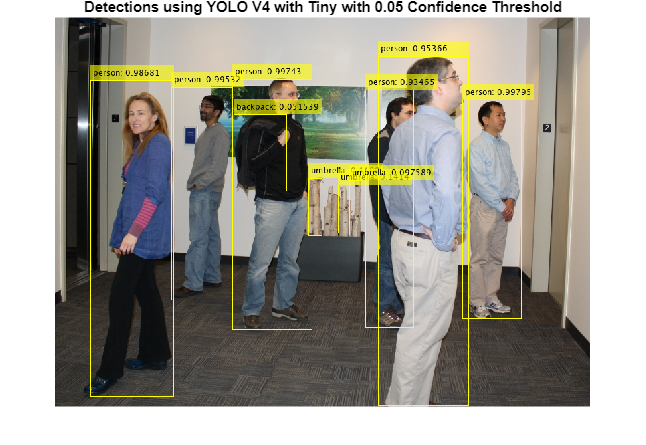

[bboxes,scores,labels] = detect(v4dark,img,"Threshold",0.05);
txt = string(labels) + ": " + scores;
imgVdark = insertObjectAnnotation(img,"rectangle",bboxes,txt);
imshow(imgVdark)
title("Detections using YOLO V4 with Tiny with 0.05 Confidence Threshold")

### You try with YOLOX

Pick one of the YOLOX detectors and *decrease the confidence threshold to 0.05*. What additional detections are returned?

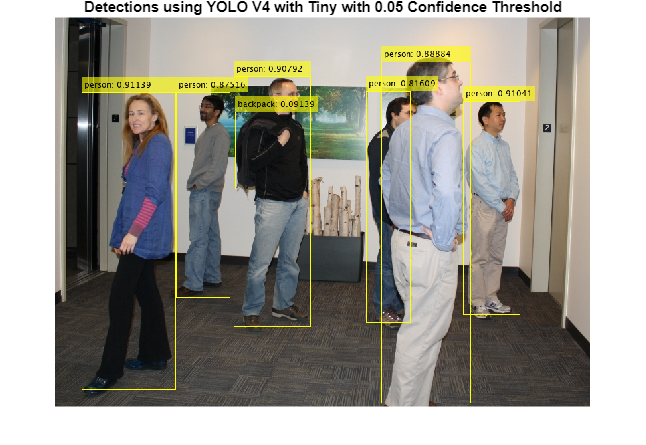

[bboxes,scores,labels] = detect(yoloXsmall,img,"Threshold",0.05);
txt = string(labels) + ": " + scores;
imgXsmall = insertObjectAnnotation(img,"rectangle",bboxes,txt);
imshow(imgXsmall)
title("Detections using YOLO V4 with Tiny with 0.05 Confidence Threshold")

## Apply the Detectors to Video

Videos are processed as a sequence of individual images. Because videos consist of many frames, it is inefficient to load an entire video into memory.

Use the `VideoReader `and `VideoWriter` objects to read in frames from a video and write frames to a new video, respectively. The code below walks through an example using the YOLOX model with the tiny backbone. The example uses a video file named pedtracking.mp4. This video is included in the Automated Driving Toolbox, which is available using the license provided for this course. 

Run this section to create the `VideoReader` and `VideoWriter` objects and view their properties.

vid = VideoReader("pedtracking.mp4")

vid =   VideoReader with properties:

   General Properties:
            Name: 'pedtracking.mp4'
            Path: 'C:\Program Files\MATLAB\R2023b\toolbox\driving\drivingdata'
        Duration: 85.3666
     CurrentTime: 0.0333
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



vidOut = VideoWriter("pedTrackingWithDetections.mp4", "MPEG-4")

vidOut =   VideoWriter

    General Properties:

       Filename:                 'pedTrackingWithDetections.mp4'
       Path:                     'F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\C2-ObjectDetection\Module 1'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


**Note**: Running this section will write a short video named "pedTrackingWithDetections.mp4" to your Current Folder. It may also take a minute or two to run.

The video is a bit long, and detecting objects in every frame will take some time. In this example, we'll process 6 seconds of the video. Update these variables if you want to process a different portion of the video or a longer duration.

startTime = 6;
endTime = 12;

The code below sets the `CurrentTime `property of the `VideoReader` object to the `startTime`. Then, a while loop is used to read frames from the videos while the `CurrentTime` is less than or equal to the end time.

Inside the while loop:

- read the current frame in the video

- apply the detector to the current frame

- create a new image with the detection results added

- write the frame to the `VideoWriter` object

Before the while loop, you must open the `VideoWriter` object for writing. You must also close it when finished.

Notice that the confidence threshold was set to 0.5. 

open(vidOut)
vid.CurrentTime = startTime;
while vid.CurrentTime <= endTime
    % read frame of the video
    % the VideoReader automatically updates each iteration in the loop
    frame = readFrame(vid);

    % apply the yoloXtiny detector
    [bboxes, scores, labels] = detect(yoloXtiny, frame, "Threshold", 0.5);

    % add the detection results as before
    txt = string(labels) + ":" + scores;
    newFrame = insertObjectAnnotation(frame, "rectangle", bboxes, txt);

    % write the results
    writeVideo(vidOut, newFrame)

end
close(vidOut)

### View the Results

Watch the video with your preferred video player or open the Video Viewer App from the Apps tab to view it in MATLAB. How did the detector do? Modify the code above to try a different detector. Using the YOLO v4 with Darknet backbone will take a long time as that detector is much slower than the other because the backbone is much larger.

*Copyright 2024 The MathWorks, Inc.*